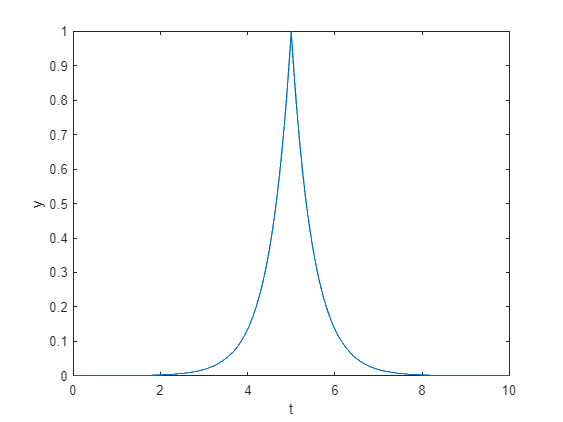

t = 0:tau:T-tau;
x = exp(2.*abs(t));
tau = 0.01; T=10;
y=zeros(1, length(t));
for k=1:length(t)
    if t(k)>=5
        y(k)=exp(-2*(t(k)-5));
    else
        y(k)=exp(2*(t(k)-5));
    end
end
N = length(y);
figure(1); plot(t,y); xlabel('t'); ylabel('y')

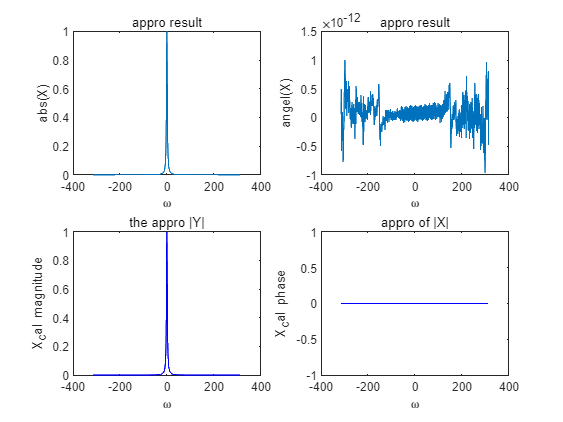

Y = fftshift(tau*fft(y));
w = -(pi/tau)+(0:N-1)*(2*pi/(N*tau));

for k=1:length(w)
    X(k)=exp(-1*j*5*w(k))*Y(k);
end
figure(2)
subplot(2,2,1); plot(w, abs(X)); xlabel('\omega'); ylabel('abs(X)');title('appro result')
subplot(2,2,2); plot(w, angle(X)); xlabel('\omega'); ylabel('angel(X)');title('appro result')
for k=1:length(w)
    X_cal = 1./(2+j*w) + 1./(2-j*w);
end
subplot(2,2,3);plot(w,abs(X_cal),'b'); xlabel('\omega');ylabel('X_cal magnitude'), title('the appro |Y|')
subplot(2,2,4);plot(w,angle(X_cal),'b'); xlabel('\omega');ylabel('X_cal phase'), title('appro of |X|')

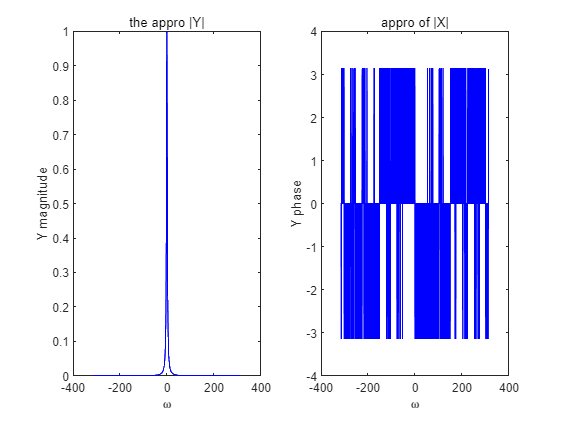

figure(3)
subplot(1,2,1);plot(w,abs(Y),'b'); xlabel('\omega');ylabel('Y magnitude'), title('the appro |Y|')
subplot(1,2,2);plot(w,angle(Y),'b'); xlabel('\omega');ylabel('Y phase'), title('appro of |X|')